%% rx_ofdm_basic.m
clear; clc;
load('tx_data.mat','bits','N','cp','M');   % original tx bits for comparison
load('rx_data.mat','rx_sig','SNR_dB');

k = log2(M);

% Remove cyclic prefix (we have 1 OFDM symbol)
rx_no_cp = rx_sig(cp+1 : cp+N);

% FFT to frequency domain
rx_freq = fft(rx_no_cp, N);

% Demodulate symbols -> symbol indices 0..M-1
rx_sym_idx = pskdemod(rx_freq, M, pi/4, 'gray');   % length N

% Convert symbol indices back to bits
rx_bits_matrix = de2bi(rx_sym_idx, k, 'left-msb'); % N x k matrix (rows = symbols)
% Make column bit vector in same order as tx bits (row-wise)
rx_bits = reshape(rx_bits_matrix.', [], 1);         % k*N x 1 column

% Ensure tx bits is column vector
tx_bits = bits(:);

% Compare (same length)
if numel(tx_bits) ~= numel(rx_bits)
    error('Length mismatch after conversion: tx %d bits, rx %d bits', numel(tx_bits), numel(rx_bits));
end

[num_err, ber] = biterr(tx_bits, rx_bits);
fprintf('BER = %g (errors = %d out of %d bits) at SNR = %d dB\n', ber, num_err, numel(tx_bits), SNR_dB);

BER = 0.460938 (errors = 59 out of 128 bits) at SNR = 15 dB


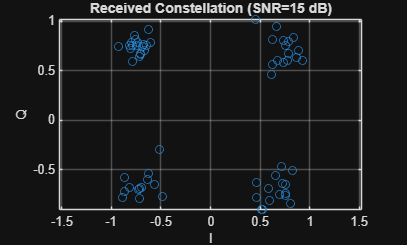


% Constellation (show demodulated symbols)
figure; plot(real(rx_freq), imag(rx_freq), 'o');
title(['Received Constellation (SNR=' num2str(SNR_dB) ' dB)']);
xlabel('I'); ylabel('Q'); grid on; axis equal;
% after plotting constellation in rx_ofdm_basic.m
saveas(gcf,'constellation.png');